# Clear workspace and command window

clear;  % Clears all variables from the workspace
clc;    % Clears the command window
disp("Cleared")

Cleared


## Step 1: Load the Hyperspectral Data

dataFile = 'f110712t01p00r18rdn_c_sc01_ort_img.mat';  % Define the name of the .mat file containing the hyperspectral data
dataStruct = load(dataFile);  % Load the data from the specified .mat file into a structure

% Display available fields in the loaded .mat file
disp('Fields in the loaded .mat file:');

Fields in the loaded .mat file:


disp(fieldnames(dataStruct));  % Display the names of all fields in the loaded .mat file

    {'Image'     }
    {'Wavelength'}



## Step 2: Identify Hyperspectral Data and Wavelength Information

% Dynamically identify the hyperspectral data field
fieldNames = fieldnames(dataStruct);  % Get the field names of the loaded data structure
bands = [];  % Initialize variable to store the hyperspectral data (3D array)
wavelengths = [];  % Initialize variable to store wavelength data

% Iterate through the fields to find the hyperspectral data and wavelength information
for i = 1:numel(fieldNames)
    fieldData = dataStruct.(fieldNames{i});  % Access the data in the current field
    if ndims(fieldData) == 3  % Check if the data is a 3D array (hyperspectral cube)
        bands = fieldData;  % Store the hyperspectral data
        disp(['Using hyperspectral data field: ', fieldNames{i}]);  % Display which field is used for hyperspectral data
    elseif isvector(fieldData) && isnumeric(fieldData)  % Check if the field is a numeric vector (wavelengths)
        wavelengths = fieldData;  % Store the wavelength data
        disp(['Using wavelength field: ', fieldNames{i}]);  % Display which field is used for wavelengths
    end
end

Using hyperspectral data field: Image


Using wavelength field: Wavelength



% Error checks to ensure data is loaded correctly
if isempty(bands)
    error('No 3D hyperspectral data found in the .mat file.');  % Display an error if no hyperspectral data is found
end

if isempty(wavelengths)
    error('No wavelength information found in the .mat file.');  % Display an error if no wavelength data is found
end

% Display data dimensions
[h, w, d] = size(bands);  % Get the dimensions of the hyperspectral data (height, width, depth)
disp(['Data dimensions: ', num2str(h), ' x ', num2str(w), ' x ', num2str(d)]);  % Display the dimensions

Data dimensions: 4802 x 907 x 224


disp(['Number of wavelengths: ', num2str(length(wavelengths))]);  % Display the number of wavelengths in the data

Number of wavelengths: 224


## Step 3: Identify CO₂ Absorption Bands


% CO₂ absorption wavelength ranges (in nanometers)
co2_nir_range = [1570, 1610];  % NIR (Near-Infrared) CO₂ absorption range
co2_swir_range = [2000, 2060]; % SWIR (Shortwave Infrared) CO₂ absorption range

% Find the indices of the bands within the CO₂ absorption ranges
co2_nir_indices = find(wavelengths >= co2_nir_range(1) & wavelengths <= co2_nir_range(2));  % Find NIR indices
co2_swir_indices = find(wavelengths >= co2_swir_range(1) & wavelengths <= co2_swir_range(2)); % Find SWIR indices

% Display NIR CO₂ indices
if ~isempty(co2_nir_indices)
    disp(['NIR CO₂ band indices: ', sprintf('%d ', co2_nir_indices)]);  % Display NIR CO₂ band indices
else
    disp('No NIR CO₂ bands found.');  % Display message if no NIR CO₂ bands found
end

NIR CO₂ band indices: 129 130 131 132 



% Display SWIR CO₂ indices
if ~isempty(co2_swir_indices)
    disp(['SWIR CO₂ band indices: ', sprintf('%d ', co2_swir_indices)]);  % Display SWIR CO₂ band indices
else
    disp('No SWIR CO₂ bands found.');  % Display message if no SWIR CO₂ bands found
end

SWIR CO₂ band indices: 175 176 177 178 179 180 


## Step 4: Extract and Visualize CO₂ Bands

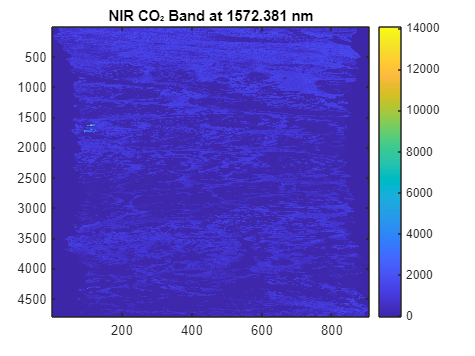

% Check if any CO₂ bands were found
if isempty(co2_nir_indices) && isempty(co2_swir_indices)
    error('No CO₂ bands found within the specified ranges.');  % Display an error if no CO₂ bands were found
end

% Visualize the first NIR CO₂ band if available
if ~isempty(co2_nir_indices)
    co2_nir_band = bands(:, :, co2_nir_indices(1));  % Extract the first NIR CO₂ band
    figure;  % Create a new figure for visualization
    imagesc(co2_nir_band);  % Display the NIR CO₂ band as an image
    colorbar;  % Add a color bar to the figure
    title(['NIR CO₂ Band at ', num2str(wavelengths(co2_nir_indices(1))), ' nm']);  % Add a title with the wavelength
end

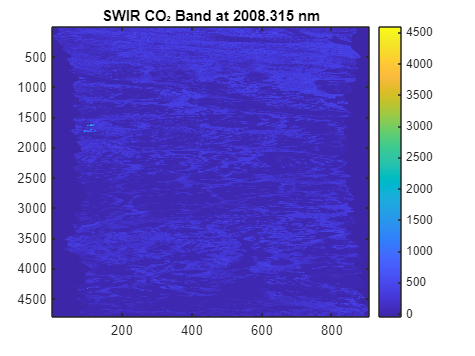


% Visualize the first SWIR CO₂ band if available
if ~isempty(co2_swir_indices)
    co2_swir_band = bands(:, :, co2_swir_indices(1));  % Extract the first SWIR CO₂ band
    figure;  % Create a new figure for visualization
    imagesc(co2_swir_band);  % Display the SWIR CO₂ band as an image
    colorbar;  % Add a color bar to the figure
    title(['SWIR CO₂ Band at ', num2str(wavelengths(co2_swir_indices(1))), ' nm']);  % Add a title with the wavelength
end

## Step 5: Optional - Save CO₂ Band Images

% Save NIR CO₂ band image if available
if exist('co2_nir_band', 'var')
    outputNirFile = 'co2_nir_band_image.mat';  % Define the output file name for NIR CO₂ band image
    save(outputNirFile, 'co2_nir_band');  % Save the NIR CO₂ band image to the specified file
    disp(['NIR CO₂ band image saved to ', outputNirFile]);  % Display a message confirming the file was saved
end

NIR CO₂ band image saved to co2_nir_band_image.mat



% Save SWIR CO₂ band image if available
if exist('co2_swir_band', 'var')
    outputSwirFile = 'co2_swir_band_image.mat';  % Define the output file name for SWIR CO₂ band image
    save(outputSwirFile, 'co2_swir_band');  % Save the SWIR CO₂ band image to the specified file
    disp(['SWIR CO₂ band image saved to ', outputSwirFile]);  % Display a message confirming the file was saved
end

SWIR CO₂ band image saved to co2_swir_band_image.mat


## Step 6: Visuailization

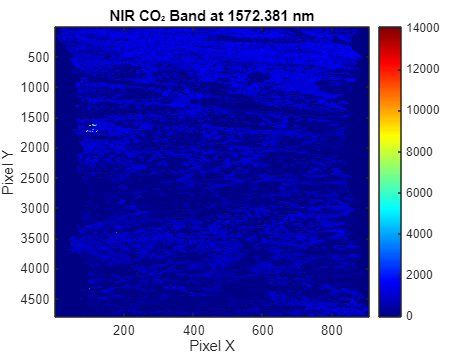

% Visualize NIR CO₂ band with 'jet' colormap
figure;  % Create a new figure
imagesc(co2_nir_band);  % Display the NIR CO₂ band as an image
colormap(jet);  % Apply the 'jet' colormap to the image
colorbar;  % Add a color bar to the figure
title('NIR CO₂ Band at 1572.381 nm');  % Add a title with the specific wavelength
xlabel('Pixel X');  % Label the x-axis
ylabel('Pixel Y');  % Label the y-axis

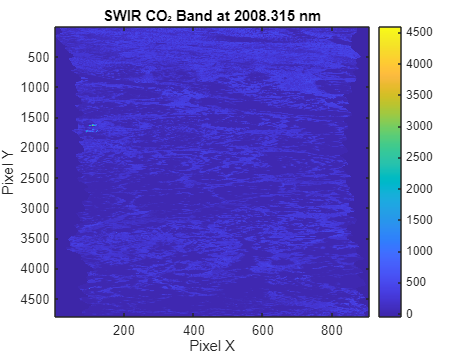


% Visualize SWIR CO₂ band with 'parula' colormap
figure;  % Create a new figure
imagesc(co2_swir_band);  % Display the SWIR CO₂ band as an image
colormap(parula);  % Apply the 'parula' colormap to the image
colorbar;  % Add a color bar to the figure
title('SWIR CO₂ Band at 2008.315 nm');  % Add a title with the specific wavelength
xlabel('Pixel X');  % Label the x-axis
ylabel('Pixel Y');  % Label the y-axis

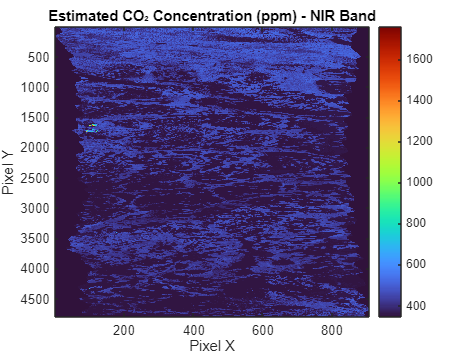


% Example calibration parameters (you need real data to refine these)
scalingFactor = 0.1;  % Example scaling factor for converting the image values to CO₂ concentration
offset = 350;         % Example baseline CO₂ concentration in ppm

% Convert NIR band to CO₂ concentration
co2_nir_ppm = co2_nir_band * scalingFactor + offset;  % Apply the scaling factor and offset to calculate CO₂ concentration in ppm

% Convert SWIR band to CO₂ concentration
co2_swir_ppm = co2_swir_band * scalingFactor + offset;  % Apply the scaling factor and offset to calculate CO₂ concentration in ppm

% Visualize CO₂ concentration (NIR)
figure;  % Create a new figure
imagesc(co2_nir_ppm);  % Display the estimated CO₂ concentration from the NIR band
colormap(turbo);  % Apply the 'turbo' colormap to the image
colorbar;  % Add a color bar to the figure
title('Estimated CO₂ Concentration (ppm) - NIR Band');  % Add a title
xlabel('Pixel X');  % Label the x-axis
ylabel('Pixel Y');  % Label the y-axis

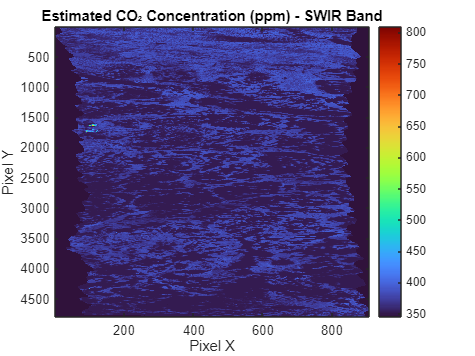


% Visualize CO₂ concentration (SWIR)
figure;  % Create a new figure
imagesc(co2_swir_ppm);  % Display the estimated CO₂ concentration from the SWIR band
colormap(turbo);  % Apply the 'turbo' colormap to the image
colorbar;  % Add a color bar to the figure
title('Estimated CO₂ Concentration (ppm) - SWIR Band');  % Add a title
xlabel('Pixel X');  % Label the x-axis
ylabel('Pixel Y');  % Label the y-axis

## Step 6: Mapping on World Map

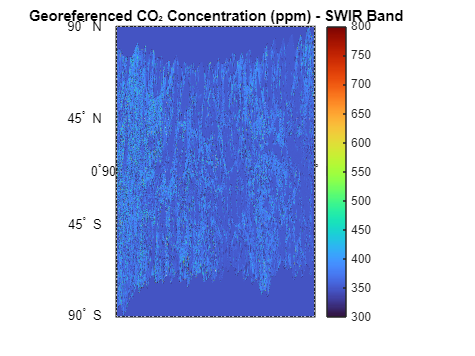

% Define latitude and longitude limits
latlim = [-90, 90];
lonlim = [-90, 90];

% Generate latitude and longitude grids
[rows, cols] = size(co2_swir_ppm);  % Get the number of rows and columns from the CO₂ concentration image (SWIR band)
lat = linspace(latlim(1), latlim(2), rows);  % Create a vector of latitude values from the minimum to maximum latitude, based on the number of rows in the image
lon = linspace(lonlim(1), lonlim(2), cols);  % Create a vector of longitude values from the minimum to maximum longitude, based on the number of columns in the image
[Lat, Lon] = meshgrid(lon, lat);  % Create a 2D grid of latitude and longitude coordinates using meshgrid function

% Replace NaNs with zeros
co2_swir_ppm(isnan(co2_swir_ppm)) = 0;  % Replace any NaN values in the CO₂ concentration image with zeros (for proper visualization)

% Plot the georeferenced data for SWIR CO₂ concentration
figure;  % Create a new figure for the plot
worldmap(latlim, lonlim);  % Set up the world map with specified latitude and longitude limits
geoshow(Lat, Lon, co2_swir_ppm, 'DisplayType', 'surface');  % Display the CO₂ concentration data (SWIR band) on the map as a surface plot
colormap(turbo);  % Apply the 'turbo' colormap to the surface plot for better visualization
colorbar;  % Add a color bar to indicate the CO₂ concentration scale
caxis([300, 800]);  % Adjust the color scale to range from 300 to 800 ppm for better contrast
title('Georeferenced CO₂ Concentration (ppm) - SWIR Band');  % Add a title to the plot

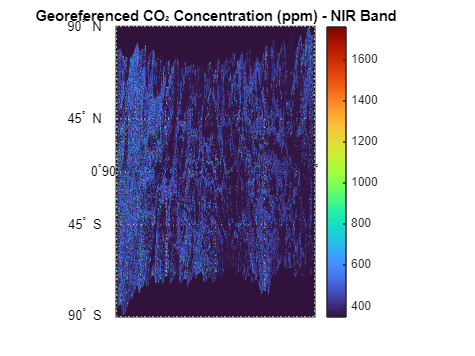


% Plot NIR CO₂ ppm on a world map
figure;  % Create a new figure for the plot
worldmap(latlim, lonlim);  % Set up the world map with the same latitude and longitude limits
geoshow(Lat, Lon, co2_nir_ppm, 'DisplayType', 'surface');  % Display the CO₂ concentration data (NIR band) on the map as a surface plot
colormap(turbo);  % Apply the 'turbo' colormap to the surface plot for better visualization
colorbar;  % Add a color bar to indicate the CO₂ concentration scale
title('Georeferenced CO₂ Concentration (ppm) - NIR Band');  % Add a title to the plot